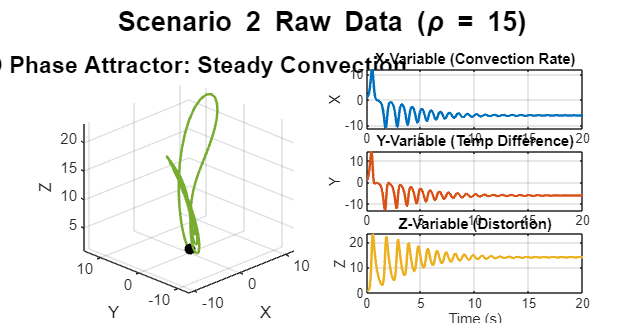


% LORENZ SCENARIO 2: STEADY CONVECTION (rho = 15)

clear; clc; close all;

% 1. DATA GENERATION & INTERPOLATION
sigma = 10; rho = 15; beta = 8/3;
t_raw = linspace(0, 20, 1000); 
lorenz_odes = @(t, s) [sigma*(s(2)-s(1)); s(1)*(rho-s(3))-s(2); s(1)*s(2)-beta*s(3)];
[t_solve, states] = ode45(lorenz_odes, t_raw, [1; 1; 1]);

t_1000 = linspace(0, 20, 1000);
x = interp1(t_solve, states(:,1), t_1000)';
y = interp1(t_solve, states(:,2), t_1000)';
z = interp1(t_solve, states(:,3), t_1000)';

% 1B. INITIAL DATA CHARACTERIZATION (RAW)

figure('Name', 'Scenario 2: Raw Data Characterization', 'Color', 'w', 'Position', [50, 50, 1200, 600]);

% Left Panel: 3D Phase Space Attractor
subplot(1, 2, 1);
plot3(x, y, z, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5); hold on;
plot3(x(1), y(1), z(1), 'ko', 'MarkerFaceColor', 'k'); % Start
grid on; axis tight;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('3D Phase Attractor: Steady Convection', 'FontSize', 14);
view(-45, 25);

% Right Panel: Independent Time Series
subplot(3, 2, 2);
plot(t_1000, x, 'Color', [0 0.4470 0.7410], 'LineWidth', 1.5);
title('X-Variable (Convection Rate)'); grid on; ylabel('X');

subplot(3, 2, 4);
plot(t_1000, y, 'Color', [0.8500 0.3250 0.0980], 'LineWidth', 1.5);
title('Y-Variable (Temp Difference)'); grid on; ylabel('Y');

subplot(3, 2, 6);
plot(t_1000, z, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 1.5);
title('Z-Variable (Distortion)'); grid on; ylabel('Z');
xlabel('Time (s)');

sgtitle('Scenario 2 Raw Data (\rho = 15)', 'FontSize', 16, 'FontWeight', 'bold');


% 2. FEATURE EXPANSION (UPLIFTING)
xy = x .* y; xz = x .* z; yz = y .* z;
x_sq = x.^2; y_sq = y.^2; z_sq = z.^2;

% 3. KOOPMAN LIFTING & HANKELIZATION
mu_x = mean(x); std_x = std(x); norm_x = (x - mu_x)/std_x;
mu_y = mean(y); std_y = std(y); norm_y = (y - mu_y)/std_y;
mu_z = mean(z); std_z = std(z); norm_z = (z - mu_z)/std_z;

Lifted = [norm_x'; norm_y'; norm_z'; ...
          norm_x'.*norm_y'; norm_x'.*norm_z'; ...
          norm_x'.^2; norm_y'.^2; norm_z'.^2];
          
L = 25; num_vars = 8; N = length(norm_x); K = N - L + 1;
H = zeros(num_vars * L, K);
for k = 1:K, window = Lifted(:, k:k+L-1); H(:, k) = window(:); end

% 4. DMD OPERATOR & FORECASTING
train_cols = floor(K * 0.4); 
H_train = H(:, 1:train_cols);
X = H_train(:, 1:end-1); X_prime = H_train(:, 2:end);

[U, S, V] = svd(X, 'econ');
r = 50; % Rank truncation
Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);

A_tilde = (Ur') * X_prime * Vr / Sr;
[W, D] = eig(A_tilde); lambdas = diag(D);
Phi = X_prime * Vr / Sr * W; 
b = Phi \ X(:, 1);           

time_dynamics = zeros(r, K);
for step = 0:K-1, time_dynamics(:, step+1) = (b .* (lambdas .^ step)); end
signal_forecast_norm = real(Phi * time_dynamics);

% 5. UN-NORMALIZE ALL VARIABLES
pred_x = (signal_forecast_norm(1,:) .* std_x) + mu_x;
pred_y = (signal_forecast_norm(2,:) .* std_y) + mu_y;
pred_z = (signal_forecast_norm(3,:) .* std_z) + mu_z;
truth_x = (H(1,:) .* std_x) + mu_x;

% Metrics
actual = truth_x(train_cols+1:end); predicted = pred_x(train_cols+1:end);
rmse = sqrt(mean((actual - predicted).^2));

% 6. DISPLAY STATISTICS
fprintf('Scenario 2: Steady State (\rho = 15) \n');

--- Scenario 2: Steady State (
ho = 15) ---


fprintf('Matrix Size: %d x %d | Rank: %d\n', size(H,1), size(H,2), r);

Matrix Size: 200 x 976 | Rank: 50


fprintf('Training Pts: %d | Forecast Pts: %d\n', train_cols, length(actual));

Training Pts: 390 | Forecast Pts: 586


fprintf('RMSE: %.6f\n', rmse);

RMSE: 0.545031


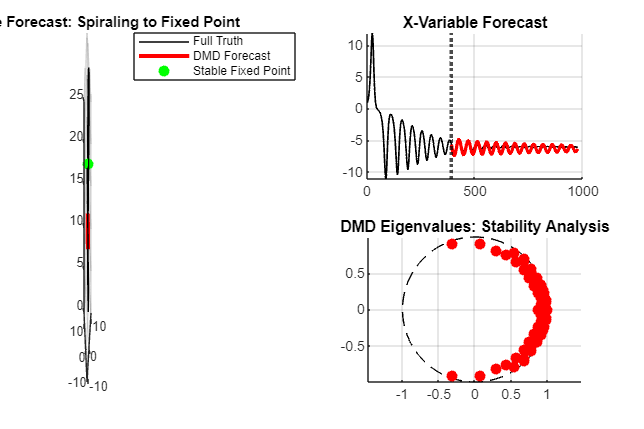


% 7. DASHBOARD VISUALIZATION
figure('Name', 'Steady Convection Analysis', 'Color', 'w', 'Position', [50, 50, 1200, 800]);

% 3D Phase Space
subplot(2, 2, [1, 3]);
plot3(x, y, z, 'k-', 'LineWidth', 0.5); hold on;
plot3(pred_x(train_cols+1:end), pred_y(train_cols+1:end), pred_z(train_cols+1:end), 'r-', 'LineWidth', 2.5);
plot3(sqrt(beta*(rho-1)), sqrt(beta*(rho-1)), rho-1, 'go', 'MarkerFaceColor', 'g'); % Fixed Point
grid on; view(-45, 25); title('3D Phase Forecast: Spiraling to Fixed Point');
legend('Full Truth', 'DMD Forecast', 'Stable Fixed Point');

% X-Variable Time Series
subplot(2, 2, 2); hold on;
plot(1:K, truth_x, 'k', 'LineWidth', 1);
plot(train_cols+1:K, predicted, 'r-', 'LineWidth', 2);
xline(train_cols, 'k:', 'LineWidth', 2); title('X-Variable Forecast'); grid on;

% Eigenvalues
subplot(2, 2, 4); hold on;
th = linspace(0,2*pi,100); plot(cos(th), sin(th), 'k--');
plot(real(lambdas), imag(lambdas), 'ro', 'MarkerFaceColor', 'r');
title('DMD Eigenvalues: Stability Analysis'); grid on; axis equal;